Running simulation for T = 50 K


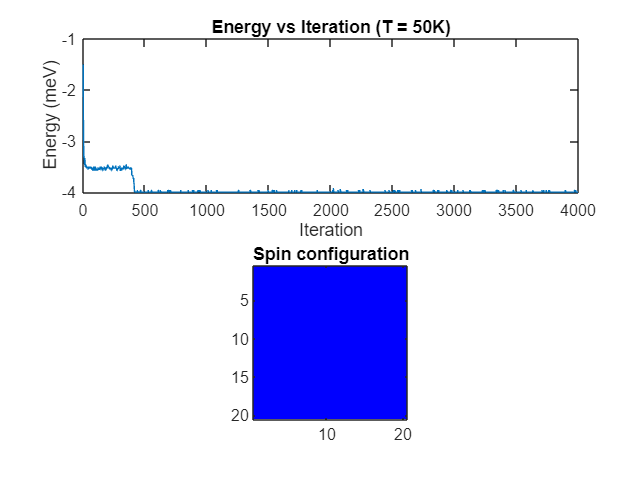

Running simulation for T = 5 K


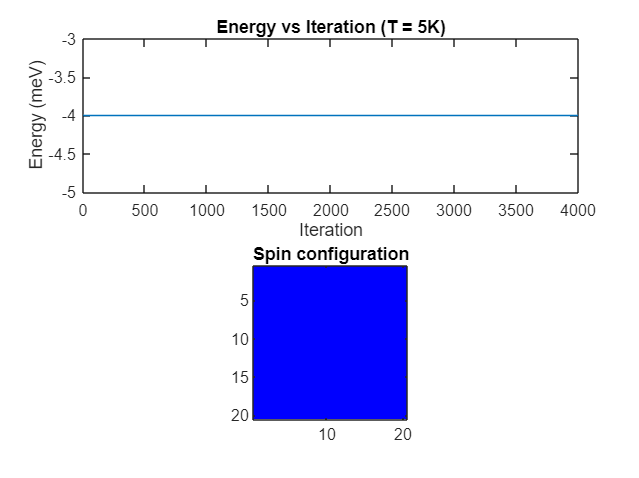

Running simulation for T = 200 K


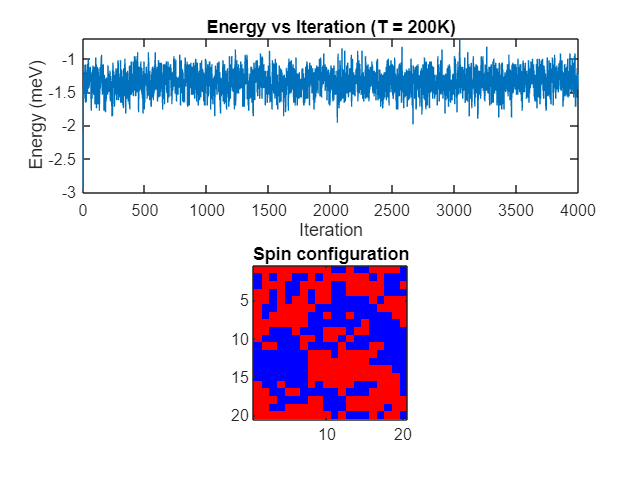

 % Constants and parameters
    N = 20;            
    J = 5e-3;          
    kB = 8.617333e-5;  
    mu = 1;            
    
    % Initialize the spin lattice with random +1 and -1 spins
    spins = initialize_lattice(N);
    
    % Define temperature range and steps for the simulation
    temperatures = [50, 5, 200];  
    num_iterations = 4000;        
    
    % Pre-allocate arrays for energy and magnetization
    energy_arr = zeros(num_iterations, 1);
    magnetization_arr = zeros(num_iterations, 1);
    
    % Loop through each temperature
    for T = temperatures
        fprintf('Running simulation for T = %d K\n', T);
        beta = 1 / (kB * T);
        
        % Perform equilibration and production steps
        for iter = 1:num_iterations
            [spins, energy, magnetization] = metropolis_step(spins, N, J, beta, mu);
            energy_arr(iter) = energy;
            magnetization_arr(iter) = magnetization;
        end
        
        % Plot energy and magnetization during equilibration
        figure;
        subplot(2,1,1);
        plot(energy_arr);
        title(sprintf('Energy vs Iteration (T = %dK)', T));
        xlabel('Iteration');
        ylabel('Energy (meV)');
        
        subplot(2,1,2);
        plot(magnetization_arr);
        title(sprintf('Magnetization vs Iteration (T = %dK)', T));
        xlabel('Iteration');
        ylabel('Magnetization (M)');
        
        % Display final spin configuration
        plot_spins(spins, N);
    end

function spins = initialize_lattice(N)
    % Randomly initialize the spin lattice with +1 and -1 values
    spins = 2 * randi([0, 1], N, N) - 1;
end

function [spins, total_energy, total_magnetization] = metropolis_step(spins, N, J, beta, mu)
    % Perform a single Metropolis step
    for i = 1:N^2
        % Choose a random site to flip
        x = randi(N);
        y = randi(N);
        
        % Calculate energy difference ∆E for the spin flip
        dE = 2 * J * spins(x, y) * sum_neighbors(spins, x, y, N);
        
        % Apply Metropolis criterion
        if dE < 0 || rand() < exp(-beta * dE)
            % Accept the spin flip
            spins(x, y) = -spins(x, y);
        end
    end
    
    % Compute total energy and magnetization after flipping
    total_energy = calculate_total_energy(spins, N, J);
    total_magnetization = mu * sum(spins(:));
end

function energy = calculate_total_energy(spins, N, J)
    % Calculate the total interaction energy
    energy = 0;
    for x = 1:N
        for y = 1:N
            energy = energy - J * spins(x, y) * sum_neighbors(spins, x, y, N);
        end
    end
    energy = energy / 2;  % Avoid double-counting interactions
end

function neighbor_sum = sum_neighbors(spins, x, y, N)
    % Implement periodic boundary conditions
    left = spins(x, mod(y-2, N) + 1);
    right = spins(x, mod(y, N) + 1);
    up = spins(mod(x-2, N) + 1, y);
    down = spins(mod(x, N) + 1, y);
    
    neighbor_sum = left + right + up + down;
end

function plot_spins(spins, N)
    % Plot the spin configuration
    imagesc(spins);
    colormap([1 0 0; 0 0 1]);  
    title('Spin configuration');
    axis equal;
    axis tight;
end
